# 题目7：仅平滑R/G/B分量

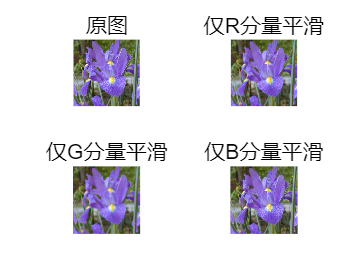

R_smooth = imfilter(img_rgb(:,:,1), h_filter, 'replicate');
G_smooth = imfilter(img_rgb(:,:,2), h_filter, 'replicate');
B_smooth = imfilter(img_rgb(:,:,3), h_filter, 'replicate');
img_smooth_R = cat(3, R_smooth, img_rgb(:,:,2), img_rgb(:,:,3));
img_smooth_G = cat(3, img_rgb(:,:,1), G_smooth, img_rgb(:,:,3));
img_smooth_B = cat(3, img_rgb(:,:,1), img_rgb(:,:,2), B_smooth);

% 显示结果
figure;
subplot(2,2,1), imshow(img_rgb), title('原图');
subplot(2,2,2), imshow(img_smooth_R), title('仅R分量平滑');
subplot(2,2,3), imshow(img_smooth_G), title('仅G分量平滑');
subplot(2,2,4), imshow(img_smooth_B), title('仅B分量平滑');